# Simulation

## Parameters

initSim

Cbase1v = 1.4847e+03

SCR_grid = 1.5000

z_grid = 0.6667

r_grid = 0.2108

x_grid = 0.6325

l_grid = 0.0020

R_grid = 0.0446

L_grid = 4.2599e-04

R_mv = 0.6000

L_mv = 0.0034

x_mv_tot = 113.2518

x_hv_tot = 18.8496

r_mv_tot = 0.0912

r_hv_tot = 0.0013

ans = 1.4293e+03

k_p_p_vsm = 0.6000

k_p_q_vsm = -0.0500

k_d_vsm = 70

H_vsm = 3

ki_q = 314.1593

V_dc_base = 1.1268e+03

V_dc = 1.1268e+03

C_dc = 0.0236

ans = 1.5915e-05

I_dc_base = 1.3312e+03

## Timings

Ts = 5e-6;

Tchange_gfm_ref = 3;

Tend = 12;


## Tests

% Rocof
Rocof_test_state = 0; % 0: not active, 1: active
rocof_test

rocof_time = 0.0400

rocof_slope = -25

Trocof_end = 2.0400



% Phase shifts
phase_shift_test_state = 0; % 0: not active, 1: active
phase_shifts =[2 3 5;-pi/40 -pi/20 -pi/5]'

phase_shifts =     2.0000   -0.0785
    3.0000   -0.1571
    5.0000   -0.6283




% Voltage sag
voltage_sag_test_state = 0; % 0: not active, 1: active
dTsags = 0.0001;
t_sags = [2-dTsags 2 3-dTsags 3 4-dTsags 4 5-dTsags 5 6-dTsags 6 7-dTsags 7 8-dTsags 8 9-dTsags 9 10-dTsags]+1;
v_mag_sags  = [0 0 -0.1 -0.1 0 0 -0.2 -0.2 0 0 -0.4 -0.4 0 0 -0.6 -0.6 0 0];
voltage_sags =[0 t_sags;v_mag_sags]'

voltage_sags =          0         0
    2.9999         0
    3.0000   -0.1000
    3.9999   -0.1000
    4.0000         0
    4.9999         0
    5.0000   -0.2000
    5.9999   -0.2000
    6.0000         0
    6.9999         0


## Simulation investigation

% Grid connection
SCR_grid_vec = [1.5 2 3 3 5];
X_R_ratio_grid_vec = [5 5 5 10 15];

n_cases = length(X_R_ratio_grid_vec);
for i = 1:n_cases
    SCR_grid = SCR_grid_vec(i)
    X_R_ratio_grid = X_R_ratio_grid_vec(i) %3;
    z_grid = 1/SCR_grid;
    r_grid = z_grid/sqrt(1+X_R_ratio_grid^2) % pu
    x_grid = z_grid/sqrt(1+(1/X_R_ratio_grid)^2) % pu
    R_grid = r_grid*Zbase_hv;
    L_grid = x_grid*Zbase_hv/omega_nom;
 



SCR_grid = 1.5000

X_R_ratio_grid = 5

r_grid = 0.1307

x_grid = 0.6537

SCR_grid = 2

X_R_ratio_grid = 5

r_grid = 0.0981

x_grid = 0.4903

## Run


simOut = sim("MVL\IdealGen_load_CtrlGen_abc.slx", "StopTime", "Tend");


## Simulation output

plotTitle = "SCR: 1.5 X/R: 5"

figName = "SCR1_5_XR5"

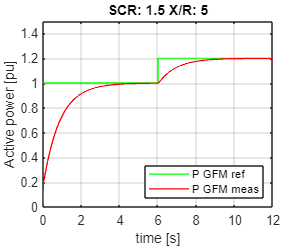

plotTitle = "SCR: 2 X/R: 5"

figName = "SCR2_0_XR5"

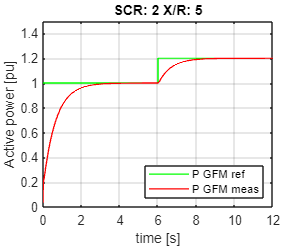


struc_voltcurr = simOut.LNpuVoltages;
struc_powers = simOut.perUnitPowers;

plotSim

strucFileName = "SCR"+num2str(floor(SCR_grid))+"_" +num2str(mod(SCR_grid,1)*10)+"_" +"XR"+X_R_ratio_grid
save("sim_data_" + strucFileName + ".mat","struc_powers","struc_voltcurr",'-mat')

strucFileName = "SCR1_5_XR5"

strucFileName = "SCR2_0_XR5"


end   
